clc; clear; close all;
tic

## 读取数据

fft_R = 512;
Radar = load("2024_09_04_152348_807084.mat").Radar;
Echo0 = Radar.data;
Echo0 = fft(conj(Echo0), fft_R*2, 2);
Echo0 = Echo0(1:end,1:fft_R);
% figure; imagesc(abs(Echo0)); title('脉冲压缩结果');
size(Echo0)

ans =        44828         512


## 扫描行标定

% Echocorr = corrcoef(Echo0(250:350,:).');
% figure; imagesc(abs(Echocorr)); title('行间互相关');
% Echocorr = corrcoef(Echo0(41369-50:41369+50,:).');
% figure; imagesc(abs(Echocorr)); title('行间互相关');

ID_range = 81:81;   %目标范围         

## 确定雷达航迹数据

Echo_move = [zeros(0,fft_R);Echo0(318:end,:)];
Nx = 336;   %322-325-332             % The sampling points in the horizontal direction
Nz = 128;                            % The sampling points in the vertical direction
Echo = zeros(Nx*Nz,fft_R);      % Echo of 1T1R
err = 12;                            % Number of movement error points
for ii = 1 : Nz
    kk = fix(ii/Nz*err);
%     kk = 0;
    Echo((ii-1)*Nx+1:ii*Nx,:) = Echo_move((ii-1)*Nx+1+kk:ii*Nx+kk,:);
end
Echo = reshape(Echo,[Nx,Nz,fft_R]);
sarData = squeeze(Echo(:,:,ID_range(ceil(length(ID_range)/2)))).';                  % Selecting echo data after pulse compression
sarData(2:2:end,:) = fliplr(sarData(2:2:end,:));
% figure; imagesc((abs(sarData)));
% , [min(abs(sarData(:))), 0.5*max(abs(sarData(:)))]

## 系统参数

dx0 = 400/Nx;                               % Sampling distance at x (horizontal) axis in mm
dy0 = 2;                               % Sampling distance at y (vertical) axis in mm
interp_factor = 1;
dx = sqrt(dx0^2+(dy0/437)^2)/interp_factor; dy = dy0/interp_factor;
nFFTspace = 1024*interp_factor;                      % Number of FFT points for Spatial-FFT
c = physconst('lightspeed');
F0 = 121*1e9;
B = 10*1e9;
Fs = Radar.fs_MHz*1e6;                % Sampling rate (sps)
Ts = 1/Fs;                            % Sampling period
Tp = 315*1e-6;
Kf = B/Tp;                        % Slope const (Hz/sec)
tI = 0;                      % Instrument delay for range calibration
k = 2*pi*F0/c;
fft2mm = Fs*c/fft_R/2/Kf*1000

fft2mm = 8.2999

## Toeplitz变换

Sr0 = squeeze(Echo(:,:,ID_range(1))).';
Sr0(2:2:end,:) = fliplr(Sr0(2:2:end,:));
% figure; imagesc((abs(Sr0)));
Sr_missing = Sr0;
Sr_missing(1:4:end,:) = 0; %制造缺失
% figure; imagesc((abs(Sr_missing)));
Sr_filled = zeros(size(Sr_missing,1),size(Sr_missing,2));
warning('off');
for ii = 1:size(Sr_missing,2)
Sr_missing_row = Sr_missing(:,ii); %提取单列
Sr_toep = toeplitz(Sr_missing_row(1:Nz/2),Sr_missing_row(Nz/2:end)); % Toeplitz变换
% figure; imagesc((abs(Sr_toep)));
% [~,s,v] = svd(Sr_toep,'econ');
% figure; plot( (1:length(diag(s)))/length(diag(s)) , diag(s)/sum(diag(s)) ,"Color","r","Marker",".");
maxv = max(max(abs(Sr_toep)));
Sr_toep_pval = (Sr_toep~=0);%zeros(Nz/2,Nz/2*1);
% for i = 1:length(d)
[X,A,B]=MC_MAX_pgm(Sr_toep/maxv,Sr_toep_pval,64,0.001,0.001,200);%S_toep,P,5,2.09,0.94,300
X = X*maxv;
fill_val = X.*Sr_toep_pval;
Sr_itoep = iTrsTP(X)';
Sr_filled(:,ii) = Sr_itoep;
    if( mod(ii,32)==0 )
        disp(['填充进度： ' num2str(ii/size(Sr_missing,2)*100) '%']);
    end
end

填充进度： 9.5238%
填充进度： 19.0476%
填充进度： 28.5714%
填充进度： 38.0952%
填充进度： 47.619%
填充进度： 57.1429%
填充进度： 66.6667%
填充进度： 76.1905%
填充进度： 85.7143%
填充进度： 95.2381%


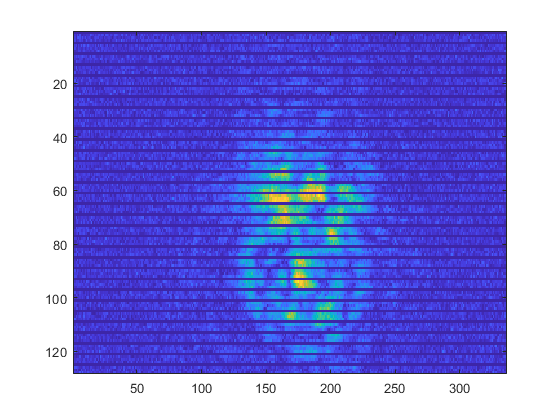

warning('on');
figure; imagesc((abs(Sr_filled)));

## RMA成像

nFFTtime = fft_R;   
% Sr = fft(Echo,nFFTtime,3);                               % Range FFT
Sr = Echo;
% figure;imagesc(abs(reshape(Sr,[],nFFTtime)));

imSize = 400;  
sarImage_2DFFT = [];
for ID_select = ID_range
%     sarData = squeeze(Sr(:,:,ID_select)).';                  % Selecting echo data after pulse compression
%     sarData(2:2:end,:) = fliplr(sarData(2:2:end,:));
    sarData = Sr_filled;
%     sarData = image_interp(sarData,interp_factor,0);
    R = c/2*(ID_select/(Kf*Ts*nFFTtime) - tI);                                          % Size of 2D image area in mm
%     R = 0.6558;
%     figure; imagesc(abs(sarData));
    wSx = 2*pi/(dx*1e-3);                                    % Sampling frequency for Target Domain
    kX = linspace(-(wSx/2),(wSx/2),nFFTspace);               % kX-Domain
    wSy = 2*pi/(dy*1e-3);                                    % Sampling frequency for Target Domain
    kY = (linspace(-(wSy/2),(wSy/2),nFFTspace)).';           % kY-Domain
    K = single(sqrt((2*k).^2 - kX.^2 - kY.^2));
    phaseFactor0 = exp(-1i*R*K);
    phaseFactor0((kX.^2 + kY.^2) > (2*k).^2) = 0;
    phaseFactor = K.*phaseFactor0;
    phaseFactor = fftshift(fftshift(phaseFactor,1),2);
    % Padding matrix with 0
    [yPointM,xPointM] = size(sarData);
    [yPointF,xPointF] = size(phaseFactor);
    if (xPointF > xPointM)
        sarData = padarray(sarData,[0 floor((xPointF-xPointM)/2)],0,'pre');
        sarData = padarray(sarData,[0 ceil((xPointF-xPointM)/2)],0,'post');
    else
        phaseFactor = padarray(phaseFactor,[0 floor((xPointM-xPointF)/2)],0,'pre');
        phaseFactor = padarray(phaseFactor,[0 ceil((xPointM-xPointF)/2)],0,'post');
    end
    
    if (yPointF > yPointM)
        sarData = padarray(sarData,[floor((yPointF-yPointM)/2) 0],0,'pre');
        sarData = padarray(sarData,[ceil((yPointF-yPointM)/2) 0],0,'post');
    else
        phaseFactor = padarray(phaseFactor,[floor((yPointM-yPointF)/2) 0],0,'pre');
        phaseFactor = padarray(phaseFactor,[ceil((yPointM-yPointF)/2) 0],0,'post');
    end
    
    sarDataFFT = fft2(sarData,nFFTspace,nFFTspace);
    sarImage_2DRMA = ifft2(sarDataFFT.*phaseFactor);
    
    [yPointT,xPointT] = size(sarImage_2DRMA);
    xRangeT = dx * (-(xPointT-1)/2 : (xPointT-1)/2);
    yRangeT = dy * (-(yPointT-1)/2 : (yPointT-1)/2);
    indXpartT = xRangeT>(-imSize/2) & xRangeT<(imSize/2);
    indYpartT = yRangeT>(-imSize/2) & yRangeT<(imSize/2);
    xRangeT = xRangeT(indXpartT);
    yRangeT = yRangeT(indYpartT);
    sarImage_2DFFT(:,:,end+1) = (sarImage_2DRMA(indYpartT,indXpartT));
end

## 输出成像结果

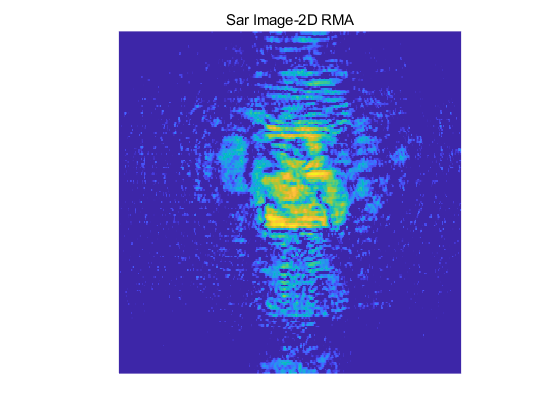

sarImage_2DFFT1 = abs(sum(sarImage_2DFFT,3));
figure;imagesc(xRangeT,yRangeT,db(sarImage_2DFFT1/max(sarImage_2DFFT1(:))),[-20,-0]);
axis equal xy off;
title 'Sar Image-2D RMA'

toc

历时 36.898953 秒。


% eval("save " + num2str(ID_select) + ".mat" + " sarImage_2DFFT")
